ODE45 EXAMPLES

First Order


$$x=\left\lbrack 0,3\right\rbrack ,y\left(0\right)=1,\frac{\mathrm{dy}}{\mathrm{dx}}=-2x^3 +x-y$$


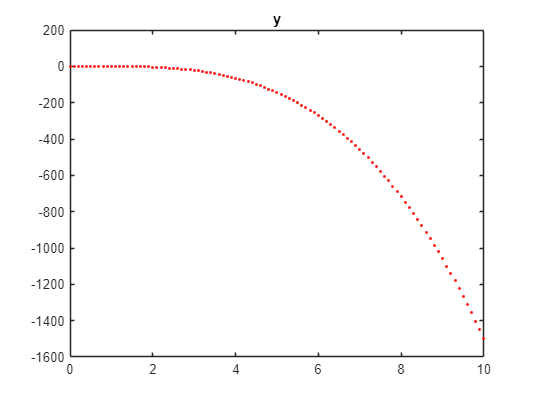

clc; clear all; close all;
% define the function dy/dx=-2x^3+x-y
F = @(x, y)(-2.*x.^3+x-y);
[x,y] = ode45(F, 0:0.1:10, 1);
plot (x, y, "r.")
title('y')

clf

Second Order

Need state variable form:

x is a column vector with incrementing derivatives e.g x(2)=second derivative

as you can see in the code you must return a column vector of x dot with the differentials


$$\frac{d^2 x}{{\mathrm{dt}}^2 }+7\frac{\mathrm{dx}}{\mathrm{dt}}+10x=20,\;x\left(0\right)=5,\overset{}{\frac{\mathrm{dx}\left(0\right)}{\mathrm{dt}}=3}$$


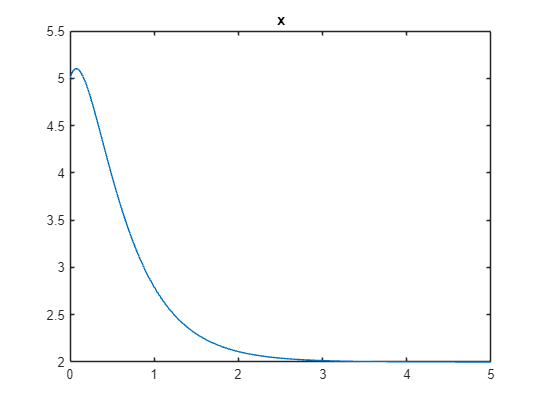

clc; clear all; close all;
function xdot = funct(t, x)
xdot(1) = x(2);
xdot(2) = 20-7*x(2)-10*x(1);
xdot=xdot';
end
[t,x]=ode45(@funct, [0, 5], [5, 3]);
% x is still a state vector so x(:, 1) is x
plot(t, x(:, 1))
title('x')

clf

System of equations


$$\begin{array}{l}
\frac{\mathrm{dA}}{\mathrm{dt}}=a*A\left(t\right)-b*B\left(t\right)\\
\frac{\mathrm{dB}}{\mathrm{dt}}=a*B\left(t\right)-b*A\left(t\right)
\end{array}$$


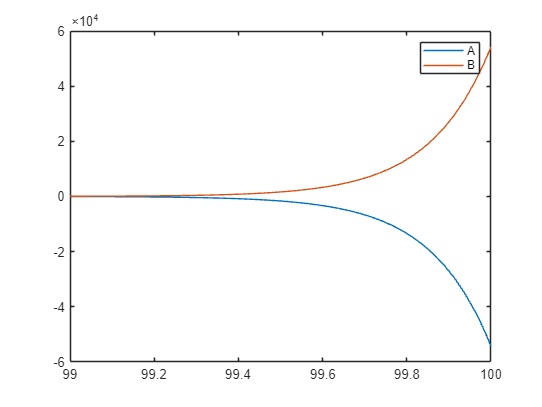

clc; clear all; close all;
% constants
a=2;
b=5;
% time span
tspan=[99, 100];
% initial conditions ([intial value for A, initial value for B])
y0=[1, 100];
% run ode45
[t, A] = ode45(@(t, y)(odefun(t, y, a, b)), tspan, y0);
% function (dAdt hold both func)
function dAdt = odefun(t, y, a, b)
% initialize array
dAdt = zeros(2, 1);
% dAdt where y hold A and B
dAdt(1) = a*y(1)-b*y(2);
dAdt(2) = a*y(2)-b*y(1);
end
% A
plot(t, A(:, 1))
hold on
% B
plot(t, A(:, 2))
hold off
legend('A', 'B')

clf